# Tópicos especiais em Estatística aplicada – 2023-2 

# EPC9 

## João Gabriel Santos Custodio

% aquisição dos dados
load("dados_epc9_8m.mat") 
m = 5;
n = 100;

#### 1) Use as 100 amostras de X para treinar um modelo PCA, mostrando o monitoramento para as 100 amostras de X e 100 amostras de Y0. Obtenha FP e FN mostrando que o modelo é adequado para o número de componentes selecionado. Informe:$\mu_x$ , número de componentes principais utilizada, variância retida, limiar utilizado para o monitoramento. 

Resposta:

Primeiramente, iremos examinar os autovalores mais relevantes da matriz de covariância e calcular a média de cada variável contida em X.

Logo em seguida, serão calculados os autovalores e autovetores de S para identificar a variância retida.

mi_X = mean(X) % calculo da média

mi_X =    12.2509    5.1681   15.1210    5.9864    0.9553


S = cov(X) % calculo da covariancia

S =     7.9011    0.0421    0.0036   -0.2935   -0.4137
    0.0421    5.3209   -0.0173   -0.1577    1.6352
    0.0036   -0.0173    0.6395    0.1606   -0.6467
   -0.2935   -0.1577    0.1606    4.3746    1.0134
   -0.4137    1.6352   -0.6467    1.0134   10.3104


% AutoVetores, AutoValores < - eig(S)
[ AutoVet, AutoVal ] = eig(S) 

AutoVet =    -0.0015   -0.0368    0.0864   -0.9864   -0.1347
    0.0250   -0.4072   -0.8681   -0.0972    0.2655
   -0.9947   -0.0846   -0.0078    0.0117   -0.0570
    0.0636   -0.8774    0.4508    0.0527    0.1419
   -0.0770    0.2365    0.1886   -0.1209    0.9423


AutoVal =     0.5796         0         0         0         0
         0    4.0315         0         0         0
         0         0    5.0432         0         0
         0         0         0    7.8702         0
         0         0         0         0   11.0221


Percebe-se que os últimos 3 autovalores de AutoVal possuem a maior contribuição para a variância. Sendo assim, pode-se relacionar os auto vetores referentes aos autovalores com maior contribuição  e calcular o acumulado da variação total  de X.

Lambda = [5.0432 0 0; 0 7.8702 0; 0 0 11.0221] % Maiores autovalores de AutoVal

Lambda =     5.0432         0         0
         0    7.8702         0
         0         0   11.0221


P = [AutoVet(:,3:5)]; % AutoVetores referentes aos maiores autovalores
auto_S = eig(S);
auto = Lambda*1/sum(auto_S)

auto =     0.1767         0         0
         0    0.2757         0
         0         0    0.3861


Variancia_Acumulada = 100*sum(diag(auto))

Variancia_Acumulada = 83.8473


display("Os 3 ultimos autovalores possuem:"+Variancia_Acumulada+"% da variância total de X");

    "Os 3 ultimos autovalores possuem:83.8473% da variância total de X"



Neste momento, procederemos à construção do modelo de previsão para a variável X, baseando-nos no produto matricial, onde T é obtido multiplicando P por X. Adicionalmente, efetuaremos o cálculo do limiar, utilizado para a avaliação de falsos positivos.

Logo em seguida, será calculada a estatística T² usando PCA

Como a média mi_X é diferente de zero, esta deve ser subtraída das variáveis de x.

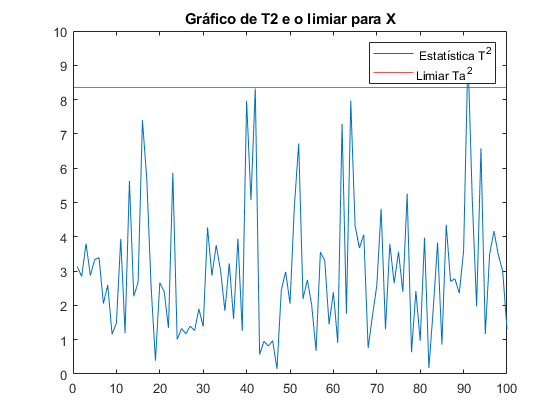

a = 3;
Ta2 = (a*(n-1)*(n+1))/(n*(n-a))*finv(0.95,a,n-a); % Cálculo do limiar
T = X*P;
X_est = T*P';

t2 = zeros(1,n);
for i = 1:1:n
t2(i) = (X_est(i,:)-mi_X)*(P*inv(Lambda)*P')*(X_est(i,:)-mi_X)'; 
end
figure
plot(1:1:n,t2)
hold on
yline(Ta2,"r")
legend(" Estatística T^2", "Limiar Ta^2")
title("Gráfico de T2 e o limiar para X") 

TP_X = length(find(t2 > Ta2)) 

TP_X = 1

FN_X = length(find(t2 <= Ta2)) 

FN_X = 99

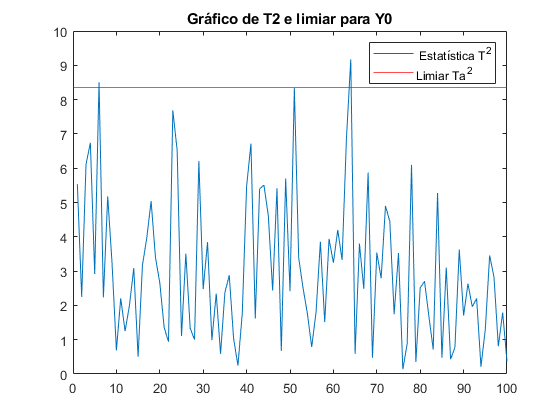


T = Y0*P;
Y0_estimado = T*P';
mi_Y0 = mean(Y0);
t2 = zeros(1,n);
for i = 1:1:n
t2(i) = (Y0_estimado(i,:)-mi_Y0)*(P*inv(Lambda)*P')*(Y0_estimado(i,:)-mi_Y0)'; end
figure
plot(1:1:n,t2)
hold on
yline(Ta2,"r")
legend(" Estatística T^2", "Limiar Ta^2")
title("Gráfico de T2 e limiar para Y0") 


TP_Y0 = length(find(t2 > Ta2)) 

TP_Y0 = 2

FN_0 = length(find(t2 <= Ta2)) 

FN_0 = 98

De acordo com o resultado acima de TP = 1 e FN = 99 para X, já para Y0 TP = 2 e FN = 98. Portanto, temos por definição que um valor de TP baixo junto com o FN alto indica que o modelo está mal-sucedido em identificar pontos fora de controle.

#### 2) Use o modelo PCA obtido para detectar as falhas nos dados de Y1 a Y6. Faça uma figura na qual se possa observar a estatística para Y1 a Y6, indicando a amostra na qual cada falha foi detectada e o limiar. Lembrando que Y1 a Y6 contém 100 amostras cada. 

O mesmo processo de cálculo efetuado para Y0 será repetido de Y1 a Y6.

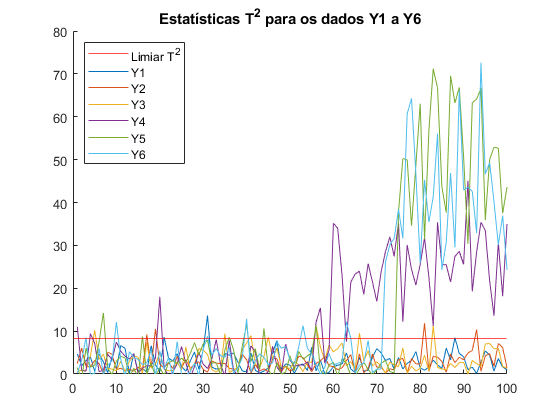

% Estatisticas T²
T2_Y1 = zeros(1, n);
T2_Y2 = zeros(1, n);
T2_Y3 = zeros(1, n);
T2_Y4 = zeros(1, n);
T2_Y5 = zeros(1, n);
T2_Y6 = zeros(1, n);

% Medias para os dados de Y1 a Y6
mi_Y1 = mean(Y1);
mi_Y2 = mean(Y2);
mi_Y3 = mean(Y3);
mi_Y4 = mean(Y4);
mi_Y5 = mean(Y5);
mi_Y6 = mean(Y6);

% T para cada dado
T1 = Y1*P;
Y1_est = T1*P';
T2 = Y2*P;
Y2_est = T2*P';
T3 = Y3*P;
Y3_est = T3*P';
T4 = Y4*P;
Y4_est = T4*P';
T5 = Y5*P;
Y5_est = T5*P';
T6 = Y6*P;
Y6_est = T6*P';

% T2 para cada dado

for i = 1:1:n
    T2_y1(i) = (Y1_est(i,:)-mi_Y1)*(P*inv(Lambda)*P')*(Y1_est(i,:)-mi_Y1)';
    T2_y2(i) = (Y2_est(i,:)-mi_Y2)*(P*inv(Lambda)*P')*(Y2_est(i,:)-mi_Y2)';
    T2_y3(i) = (Y3_est(i,:)-mi_Y2)*(P*inv(Lambda)*P')*(Y3_est(i,:)-mi_Y3)';
    T2_y4(i) = (Y4_est(i,:)-mi_Y2)*(P*inv(Lambda)*P')*(Y4_est(i,:)-mi_Y4)';
    T2_y5(i) = (Y5_est(i,:)-mi_Y2)*(P*inv(Lambda)*P')*(Y5_est(i,:)-mi_Y5)';
    T2_y6(i) = (Y6_est(i,:)-mi_Y2)*(P*inv(Lambda)*P')*(Y6_est(i,:)-mi_Y6)';
end

% Visualização dos resultados

figure
yline(Ta2,"r")
hold on
plot(1:1:n,T2_y1)
plot(1:1:n,T2_y2)
plot(1:1:n,T2_y3)
plot(1:1:n,T2_y4)
plot(1:1:n,T2_y5)
plot(1:1:n,T2_y6)
title("Estatísticas T^2 para os dados Y1 a Y6")
legend("Limiar T^2", "Y1","Y2","Y3","Y4","Y5","Y6", "location", "northwest") 
ylim([0, 80]);


% Tempos de detecção para cada conjunto de dados

Tempo_deteccao_Y1 = find(T2_y1 > Ta2);
Tempo_deteccao_Y1 =  Tempo_deteccao_Y1(1);
display("Tempo de deteccao para Y1 ="+Tempo_deteccao_Y1+" Amostras")

    "Tempo de deteccao para Y1 =21 Amostras"



Tempo_deteccao_Y2 = find(T2_y2 > Ta2);
Tempo_deteccao_Y2 =  Tempo_deteccao_Y2(1);
display("Tempo de deteccao para Y2 ="+Tempo_deteccao_Y2+" Amostras")

    "Tempo de deteccao para Y2 =17 Amostras"



Tempo_deteccao_Y3 = find(T2_y3 > Ta2);
Tempo_deteccao_Y3 =  Tempo_deteccao_Y3(1);
display("Tempo de deteccao para Y3 ="+Tempo_deteccao_Y3+" Amostras")

    "Tempo de deteccao para Y3 =5 Amostras"



Tempo_deteccao_Y4 = find(T2_y4 > Ta2);
Tempo_deteccao_Y4 =  Tempo_deteccao_Y4(1);
display("Tempo de deteccao para Y4 ="+Tempo_deteccao_Y4+" Amostras")

    "Tempo de deteccao para Y4 =1 Amostras"



Tempo_deteccao_Y5 = find(T2_y5 > Ta2);
Tempo_deteccao_Y5 =  Tempo_deteccao_Y5(1);
display("Tempo de deteccao para Y5 ="+Tempo_deteccao_Y5+" Amostras")

    "Tempo de deteccao para Y5 =7 Amostras"



Tempo_deteccao_Y6 = find(T2_y6 > Ta2);
Tempo_deteccao_Y6 =  Tempo_deteccao_Y6(1);
display("Tempo de deteccao para Y6 ="+Tempo_deteccao_Y6+" Amostras")

    "Tempo de deteccao para Y6 =3 Amostras"



#### 3) Calcule a contribuição das variáveis para as falhas de Y1 a Y6, de 1 instante antes da falha até 5 instantes após. Some a contribuição dos 6 instantes e identifique em cada caso quais variáveis tiveram maior contribuição para a estatística de cada uma das falhas. Verifique a forma mais adequada de apresentação que permita uma fácil visualização. 

Para este cálculo, foi disponibilizado uma função "contrib_pc" que calcula a contribuição.

Com isso, podemos calcular a contribuição de cada dado:

contribuicao_y1 = contrib_pc(Y1_est(1:(Tempo_deteccao_Y1+5),:),P,a,n,0.95,auto_S(3:5));
contribuicao_y2 = contrib_pc(Y2_est(1:(Tempo_deteccao_Y2+5),:),P,a,n,0.95,auto_S(3:5));
contribuicao_y3 = contrib_pc(Y3_est(Tempo_deteccao_Y3:(Tempo_deteccao_Y3+5),:),P,a,n,0.95 ...
    ,auto_S(3:5));
contribuicao_y4 = contrib_pc(Y4_est(Tempo_deteccao_Y4:(Tempo_deteccao_Y4+5),:),P,a,n,0.95 ...
    ,auto_S(3:5));
contribuicao_y5 = contrib_pc(Y5_est(Tempo_deteccao_Y5:(Tempo_deteccao_Y5+5),:),P,a,n,0.95 ...
    ,auto_S(3:5));
contribuicao_y6 = contrib_pc(Y6_est(Tempo_deteccao_Y6:(Tempo_deteccao_Y6+5),:),P,a,n,0.95 ...
    ,auto_S(3:5));

Uma vez calculadas as contribuições, podemos plotar o gráfico 3D para visualização.

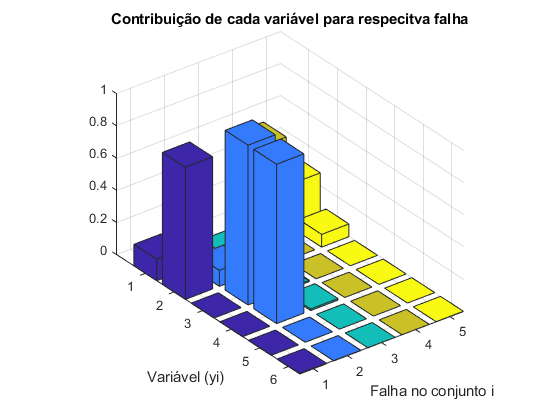

contribuicao_3d = [
    contribuicao_y1;
    contribuicao_y2;
    contribuicao_y3;
    contribuicao_y4;
    contribuicao_y5;
    contribuicao_y6;
];

figure
bar3(contribuicao_3d)
title("Contribuição de cada variável para respecitva falha")
xlabel("Falha no conjunto i")
ylabel("Variável (yi)") 

O código da função disponibilizada contrib_pc:

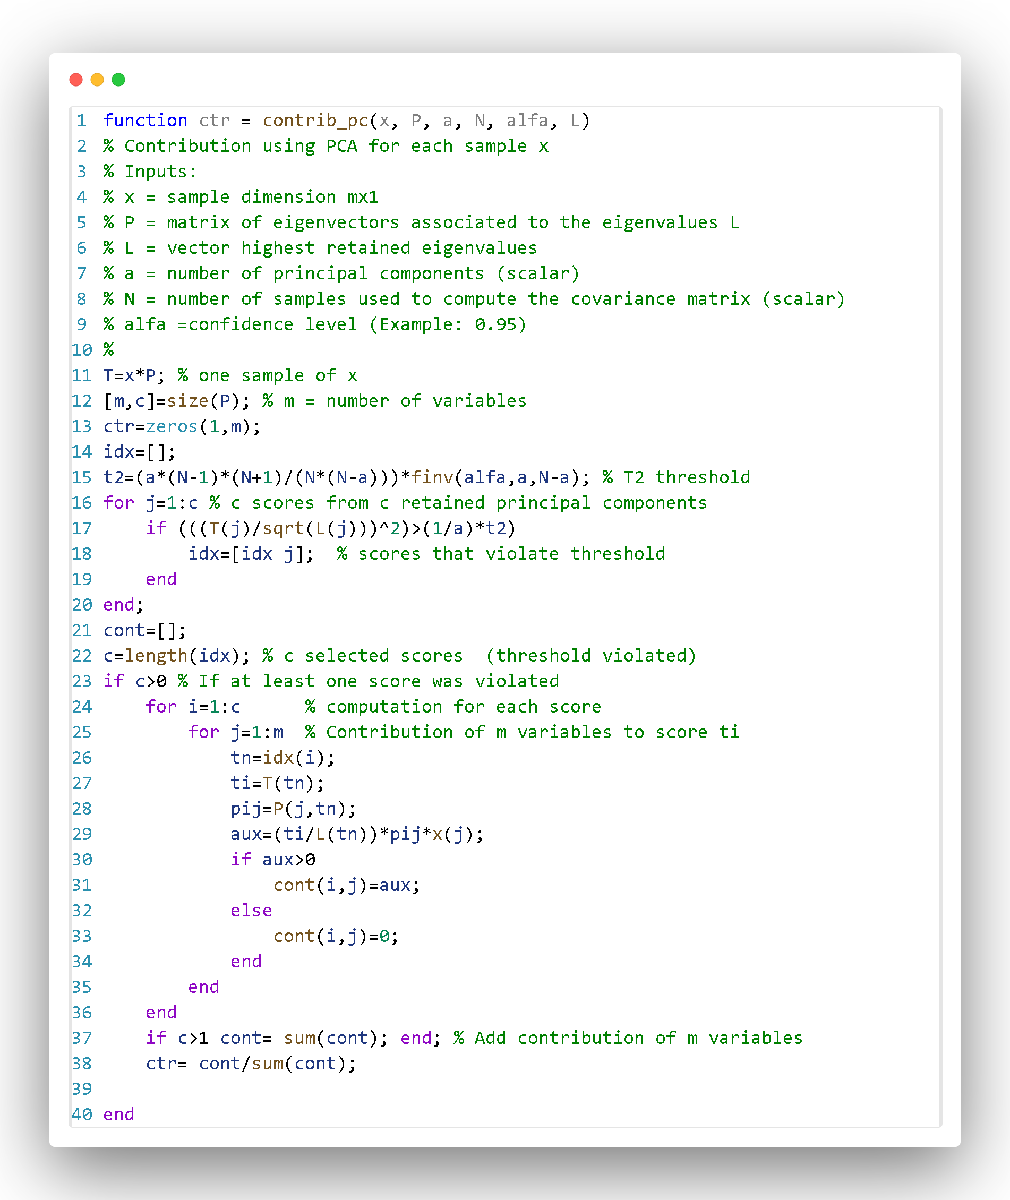

#### 4) Baseado na contribuição das variáveis para as falhas calculadas, identifique a presença de falhas semelhantes, e proponha uma forma de diagnosticar estas diferentes falhas, mostrando seu correto funcionamento. 

Reposta:

Com o gráfico de contribuições, é observado que Y3 e Y4 possuem contribuições semelhantes para  falha no conjunto 2. Isso indica que essas falhas podem ser semelhantes e podem ter a mesma causa.

Para diagnosticar essas diferentes falhas, podemos Identificar as variáveis que contribuem significativamente para as falhas através do gráfico de contribuições. Uma vez que aquela é modelada a relação para aquela falha determinada pelas variáveis correlacionadas, podemos prever o risco dessa falha ocorrer novamente caso o mesmo cenário venha a acontecer futuramente.

Neste caso para a falha no conjunto 2, temos uma contribuição praticamente nula das variáveis Y1, Y 5 e Y6, uma contribuição pequena de Y2 e uma contribuição significativa de Y3 e Y4. Dessa forma, basta que um sistema colete os dados das variáveis e quando tivermos a mesma situação acontecendo pode-se parar colocando um "limiar" para que Y3 e Y4 não chegue a valores muito altos e o problema seja resolvido.

Por fim, o gráfico de contribuição de falhas apresentado fornece informações valiosas sobre as causas das falhas. Essas informações podem ser usadas para desenvolver um sistema de monitoramento que possa ajudar a prevenir falhas. Ao implementar um sistema de monitoramento, podemos melhorar a detecção e prevenção de falhas. Isso pode ajudar a melhorar a confiabilidade do processo e reduzir o custo de produção.